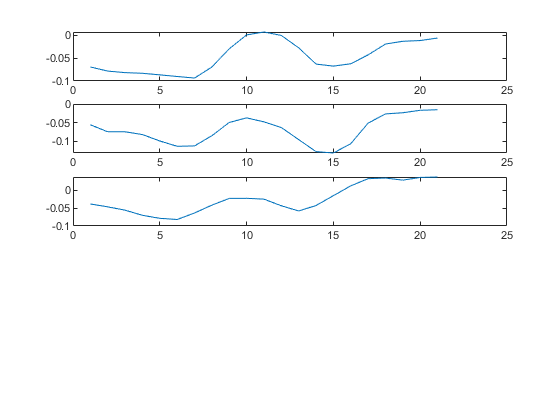

clear;
close all;
clc;

[x1, sr] = audioread('sample5/F01_22HC010H_BUS.CH1.wav');
[x2, sr] = audioread('sample5/F01_22HC010H_BUS.CH3.wav');
[x3, sr] = audioread('sample5/F01_22HC010H_BUS.CH4.wav');
[x4, sr] = audioread('sample5/F01_22HC010H_BUS.CH5.wav');
[x5, sr] = audioread('sample5/F01_22HC010H_BUS.CH6.wav');

x = [x1, x2, x3, x4, x5];
x = x';
nsample = size(x,2);
nmic = 5;
npair = nmic - 1;

figure;
subplot(5,1,1); plot(x(1,16000:16020)); % (+) delayed
subplot(5,1,2); plot(x(2,16000:16020)); % ref_mic assumed
subplot(5,1,3); plot(x(3,16000:16020)); % no idea

## make hamming window

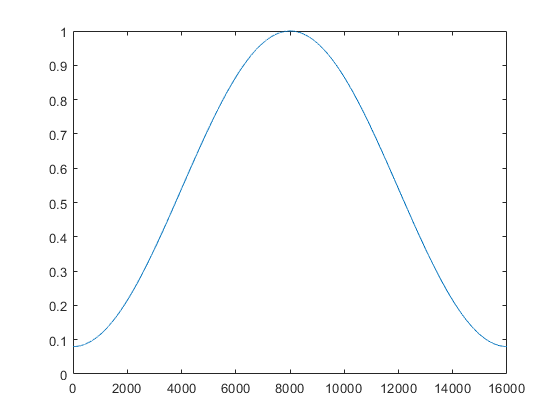



nwin = 16000; % 1 sec
%     hamm_val = 0.54 - 0.46*cos(6.283185307*i/(window-1));
win = zeros(1,nwin);
for i = 1:nwin
    win(i) = 0.54 - 0.46 * cos(6.283185307*(i-1)/(nwin-1));
end

figure; plot(win);

disp(win(1:10)');

    0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800



## testing calculating xcorr


% Comparing from frame 300 to 16300
% 1st xcorr calculation iteration 1: 0.239386
% 2nd xcorr calculation iteration 1: 0.152243
% avg xcorr between 1 and 2
% 0.230185

npiece = 200;
nfft = 16384;
nbest = 2;

scroll = floor(nsample / (npiece+2)); 

stft1 = fft([x(1,scroll:(scroll+nwin-1)) .* win, zeros(1,nfft-nwin)]); 
stft2 = fft([x(2,scroll:(scroll+nwin-1)) .* win, zeros(1,nfft-nwin)]); 

numerator = stft1 .* conj(stft2);
ccorr = real(ifft(numerator ./ (abs(numerator))));
ccorr = [ccorr(1:481), ccorr(end-480+1:end)];
best2_ccorr = maxk(ccorr, 2);

disp('scroll');

scroll


disp(scroll);

   300



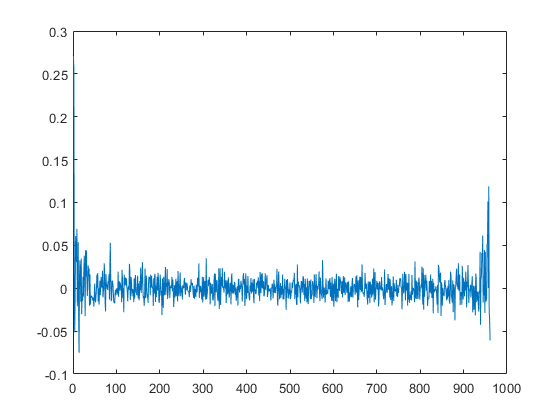

plot(ccorr);

disp(best2_ccorr); 

    0.2711    0.2552



## calculate avg_ccorr

avg_ccorr = zeros(nmic, nmic);

for i = 1:npiece
    st = i * scroll;
    ed = st + 16000 - 1;
    if st + nfft >= nsample
        break;
    end

    for m1 = 1:(nmic-1)
        avg_ccorr(m1, m1) = 0;
        for m2 = (m1+1):nmic
            stft1 = fft([x(m1,st:ed) .* win, zeros(1,nfft-nwin)]); 
            stft2 = fft([x(m2,st:ed) .* win, zeros(1,nfft-nwin)]);
            numerator = stft1 .* conj(stft2);
            ccorr = real(ifft(numerator ./ (abs(numerator))));
            ccorr = [ccorr(1:481), ccorr(end-480+1:end)];
           
            avg_ccorr(m1, m2) = avg_ccorr(m1, m2) + sum(maxk(ccorr, nbest));
            avg_ccorr(m2, m1) = avg_ccorr(m1, m2); 
        end
    end
end

avg_ccorr = avg_ccorr / (nbest * npiece * (npair));
disp(avg_ccorr);

         0    0.0686    0.0627    0.0591    0.0605
    0.0686         0    0.0592    0.0581    0.0646
    0.0627    0.0592         0    0.0728    0.0684
    0.0591    0.0581    0.0728         0    0.0727
    0.0605    0.0646    0.0684    0.0727         0



disp(sum(avg_ccorr,1)');

    0.2509
    0.2506
    0.2632
    0.2627
    0.2663



disp(max(sum(avg_ccorr,1)));

    0.2663



## calculating scaling factor

% Set the total number of segments from 10 to 1 for computing scalling factor, with segment duration 60798
% Processing channel 0
% amount_frames_read: 0.000000
% segment_duration: 0.000000
% The Median maximum energy for channel 0 is 0.352051
% Set the total number of segments from 10 to 1 for computing scalling factor, with segment duration 60798
% Processing channel 1
% amount_frames_read: 0.000000
% segment_duration: 0.000000
% The Median maximum energy for channel 1 is 0.341858
% Set the total number of segments from 10 to 1 for computing scalling factor, with segment duration 60798
% Processing channel 2
% amount_frames_read: 0.000000
% segment_duration: 0.000000
% The Median maximum energy for channel 2 is 0.499451
% Weighting calculated to adjust the signal: 0.754173

nsegment = 10;

max_val = zeros(nmic, 1);

if size(x,2) <= 160000 % 10 seconds
    for m = 1:nmic
        max_val(m) = max(abs(x(m,:)));
    end
else
    if size(x,2) < 1600000 % 100 seconds
        nsegment = ceil(size(x,2) / 16000);
    end
    scroll = floor(size(x,2) / nsegment);
    max_val_candidate = zeros(nmic, nsegment);
    
    for s = 0:(nsegment-1)
        st = s * scroll + 1;
        ed = st + scroll - 1;
        for m = 1:nmic
            max_val_candidate(m,s+1) = abs(max(x(m,st:ed)));
        end
    end
    
    for m = 1:nmic
        
        sorted = sort(max_val_candidate(m,:), 'ascend');
        max_val(m) = sorted(end/2 + 1);
    end
end

overall_weight = (0.3 * nmic) / sum(max_val);

disp(max_val);

    0.3521
    0.3756
    0.3000
    0.3419
    0.4995



disp(overall_weight);

    0.8026



% disp((0.3 * 3) / (0.352051 + 0.341858 + 0.499451));


## compute total number of delays

% int totalNumDelays
% % = (int)((m_frames - (*m_config).windowFrames - m_biggestSkew - m_UEMGap)/((*m_config).
% rate*m_sampleRateInMs));
% sr_in_ms = 16000 / 1000; % 16

% too complicated. I should do hard coding
nframe = floor(( nsample - 8000 ) / (4000));

disp(nframe);

    13



## recreating hamming window

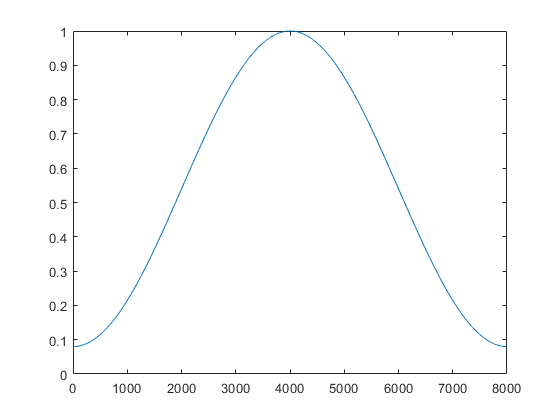

nwin = 8000; % 0.5 sec
%     hamm_val = 0.54 - 0.46*cos(6.283185307*i/(window-1));
win = zeros(1,nwin);
for i = 1:nwin
    win(i) = 0.54 - 0.46 * cos(6.283185307*(i-1)/(nwin-1));
end

figure; plot(win);

disp(win(1:10));

    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800



disp(16000 * 30 / 1000);

   480



## compute TDOA

nbest = 4;
[dummy, ref_mic] = max(sum(avg_ccorr));
%ref_mic = 2;
micpair = zeros(nmic, npair);


gcc_nbest = zeros(npair, nframe, nbest);
tdoa_nbest = zeros(npair, nframe, nbest);
lrfilp_gcc = zeros(npair, nframe, nfft);

for m = 1:nmic
    p = 1; % pair idx
    for i = 1:nmic
        if i == m
            continue;
        end
        micpair(m,p) = i;
        p = p + 1;
    end
end


for t = 1:(nframe)
    st = (t-1) * 4000 + 1;
    ed = st + nwin - 1;
%     disp(st);
%     disp(ed);
        for p = 1:npair
            
            m = micpair(ref_mic,p);
            
            stft_ref = fft([x(ref_mic,st:ed) .* win, zeros(1,nfft-nwin)]); 
            stft_m = fft([x(m,st:ed) .* win, zeros(1,nfft-nwin)]);
            numerator = stft_m .* conj(stft_ref);
            gcc = real(ifft(numerator ./ (eps+abs(numerator))));
            gcc = [gcc(end-479:end), gcc(1:480)];
            [gcc_nbest(p,t,:), tdoa_nbest(p,t,:)] = maxk(gcc, nbest);
            tdoa_nbest(p,t,:) = tdoa_nbest(p,t,:) - (481); % index shifting
          
        end

end

disp(squeeze(gcc_nbest(:,:,1)));

  1 ~ 11번 열

    0.0840    0.0958    0.3159    0.4406    0.3951    0.5243    0.3628    0.3320    0.2340    0.5149    0.3196
    0.1304    0.1247    0.4047    0.3721    0.6302    0.4966    0.4161    0.2995    0.2472    0.3946    0.4590
    0.1037    0.1352    0.3670    0.4736    0.5887    0.4686    0.5411    0.4187    0.3534    0.5520    0.5322
    0.1688    0.1912    0.4108    0.5103    0.5960    0.6375    0.5026    0.4790    0.3169    0.4470    0.4333

  12 ~ 13번 열

    0.3942    0.1622
    0.3271    0.2190
    0.4496    0.1741
    0.3144    0.2648



disp(squeeze(tdoa_nbest(:,:,1)));

     2     4     3     3     2     3     4     3     4     4     4     3     4
     2    -6     3     2     2     2     3     2     2     2     3     0     3
     0     0     0     0     0     0     1     1     1     1     1     1    -2
     2     0    -1    -1    -1    -1    -1    -1     0    -1     0    -1    -1



disp(squeeze(tdoa_nbest(:,:,2)));

    16     3     4     2     3     0     3     4     3     1     3     1     1
    -8     2     2     3     0     3     2     3     3     3     0     3    -8
     6     1     1     1     1     1     0     0     2     2     3    -2     0
     0    -1     0     2     2     0     0     0    -1     0    -1     0     0



## find noise threshold

% Threshold is 0.140125 (min: 0.132648 max 0.563892)
% Thresholding noisy frames lower than 0.140125
th_idx = floor((0.1 * nframe)) + 1;

sorted = sort(sum(gcc_nbest(:,:,1),1), 'ascend');

threshold = sorted(th_idx)/npair;
%disp(sorted);
% disp(th_idx);
disp(threshold);

    0.1367



## noise filtering

noise_filter = zeros(npair, nframe);

for p = 1:npair
    for t = 1:nframe
        if gcc_nbest(p,t,1) < threshold
            noise_filter(p,t) = 1;
        
            if t == 1  % it's silence
                gcc_nbest(p,t,:) = 0; % masking with discouraging values
                gcc_nbest(p,t,1) = 1; % only one path
                tdoa_nbest(p,t,:) = 480; % masking with discouraging values
                tdoa_nbest(p,t,1) = 0;
            else
                tdoa_nbest(p,t,:) = tdoa_nbest(p,t-1,:);
            end
        end
    end
end

disp(gcc_nbest(:,:,1));

  1 ~ 11번 열

    1.0000    0.0958    0.3159    0.4406    0.3951    0.5243    0.3628    0.3320    0.2340    0.5149    0.3196
    1.0000    0.1247    0.4047    0.3721    0.6302    0.4966    0.4161    0.2995    0.2472    0.3946    0.4590
    1.0000    0.1352    0.3670    0.4736    0.5887    0.4686    0.5411    0.4187    0.3534    0.5520    0.5322
    0.1688    0.1912    0.4108    0.5103    0.5960    0.6375    0.5026    0.4790    0.3169    0.4470    0.4333

  12 ~ 13번 열

    0.3942    0.1622
    0.3271    0.2190
    0.4496    0.1741
    0.3144    0.2648



disp(tdoa_nbest(:,:,1));

     0     0     3     3     2     3     4     3     4     4     4     3     4
     0     0     3     2     2     2     3     2     2     2     3     0     3
     0     0     0     0     0     0     1     1     1     1     1     1    -2
     2     0    -1    -1    -1    -1    -1    -1     0    -1     0    -1    -1




disp(gcc_nbest(:,:,2));

  1 ~ 11번 열

         0    0.0795    0.3060    0.1930    0.3828    0.2033    0.3329    0.1361    0.2310    0.2623    0.2912
         0    0.1145    0.1922    0.3268    0.1864    0.2997    0.2820    0.2615    0.2344    0.3583    0.2814
         0    0.0832    0.3235    0.3037    0.2260    0.4202    0.1666    0.1280    0.1855    0.2332    0.1263
    0.1297    0.1192    0.3198    0.2337    0.2307    0.2624    0.3778    0.2058    0.2509    0.4398    0.4308

  12 ~ 13번 열

    0.2259    0.1385
    0.3167    0.1628
    0.2238    0.1681
    0.2250    0.1937



disp(tdoa_nbest(:,:,2));

   480   480     4     2     3     0     3     4     3     1     3     1     1
   480   480     2     3     0     3     2     3     3     3     0     3    -8
   480   480     1     1     1     1     0     0     2     2     3    -2     0
     0    -1     0     2     2     0     0     0    -1     0    -1     0     0



## single channel viterbi - emission, trans prob

emission1 = zeros(npair, nframe, nbest);
diff1 = zeros(npair, nframe, nbest, nbest); % do not using 1st idx
transition1 = zeros(npair, nframe, nbest, nbest); % do not using 1st idx

for p = 1:npair
    for t = 1:nframe
        for n = 1:nbest 
            if gcc_nbest(p,t,n) == 0
                emission1(p,t,n) = -1000;
            else
                emission1(p,t,n) = log10(gcc_nbest(p,t,n));
            end
        end
    end
end



for p = 1:npair
    for t = 2:nframe
        for n = 1:nbest
            for nprev = 1:nbest
                diff1(p,t,n,nprev) = abs(tdoa_nbest(p,t,n) - tdoa_nbest(p,t-1,nprev));
            end
        end
    end
end

maxdiff1 = max(diff1(:));

% for p = 1:npair
%     for t = 2:nframe
%         for n = 1:nbest
%             if maxdiff1 < max(diff1(p,t,n,:));
%             maxdiff1(p,t,n) = max(diff1(p,t,n,:));
%         end
%     end
% end

for p = 1:npair
    for t = 2:nframe
        for n = 1:nbest
            for nprev = 1:nbest
                % there is a computational bug.
%                 disp((2+maxdiff1(p,t,n)));
%                 disp(diff1(p,t,n,nprev));
%                 disp(maxdiff1(p,t,n));
%                 disp(log10(481/482));
%                 disp(1 + maxdiff1(p,t,n) - diff1(p,t,n,nprev));
%                 disp((2+maxdiff1(p,t,n)));
                nume = 1 + maxdiff1 - diff1(p,t,n,nprev);
                deno = (2+maxdiff1);
                transition1(p,t,n,nprev) = log10(nume / deno); 
%                 disp(transition1(p,t,n,nprev));
            end
        end
    end
end


## single channel viterbi - searching


nbest2 = 2;
score1 = zeros(npair, nframe, nbest, nbest); % tmp variable
score1_table = zeros(npair, nframe, nbest);
back1_table = zeros(npair, nframe, nbest);
bestpath1 = zeros(npair, nframe, nbest2); % state idx stored.

for p = 1:npair
    
    for n = 1:nbest
        score1(p,1,n,:) = emission1(p,1,n); % broadcasting
        score1_table(p,1,n) = emission1(p,1,n);
    end
end

for p = 1:npair
    for t = 2:nframe
        for n = 1:nbest
            for nprev = 1:nbest
                score1(p,t,n,nprev) = ...
                    score1_table(p,t-1,nprev,1) + ...
                    25*transition1(p,t,n,nprev) + ... 
                    emission1(p,t,n);    
            end
            %score1_table(p,t,n) = max(score1(p,t,n,:));
            [score1_table(p,t,n),back1_table(p,t,n)] = max(score1(p,t,n,:));
        end
    end
end

for p = 1:npair
    [dummy, bestpath1(p,end,1)] = max(score1_table(p,end,:));
end

for p = 1:npair
    for back_t = 0:(nframe-2)        
        t = nframe - back_t;
        bestpath1(p,t-1,1) = back1_table(p,t,bestpath1(p,t,1));
    end
end

% If you put more weight on transition, the back table changes.
% If I had put weight 10 on transition, the back table became intuitive.
disp(back1_table(1,:,:)); % compare first mic pair trellis plot


(:,:,1) =

     0     1     1     1     1     2     1     2     1     1     1     1     1


(:,:,2) =

     0     1     1     1     1     1     1     1     1     2     1     1     1


(:,:,3) =

     0     1     1     1     1     1     1     1     1     2     1     1     1


(:,:,4) =

     0     1     1     1     1     2     1     2     1     1     1     1     1



disp(score1_table(1,:,:));


(:,:,1) =

  1 ~ 11번 열

         0   -1.0412   -1.6314   -2.0097   -2.4578   -2.7519   -3.2370   -3.7532   -4.4287   -4.7393   -5.2570

  12 ~ 13번 열

   -5.7061   -6.5408


(:,:,2) =

   1.0e+03 *

  1 ~ 11번 열

   -1.0000   -0.0508   -0.0017   -0.0024   -0.0024   -0.0032   -0.0033   -0.0041   -0.0044   -0.0051   -0.0053

  12 ~ 13번 열

   -0.0060   -0.0066


(:,:,3) =

   1.0e+03 *

  1 ~ 11번 열

   -1.0000   -0.0508   -0.0021   -0.0025   -0.0027   -0.0034   -0.0039   -0.0043   -0.0045   -0.0051   -0.0054

  12 ~ 13번 열

   -0.0061   -0.0066


(:,:,4) =

   1.0e+03 *

  1 ~ 11번 열

   -1.0000   -0.0509   -0.0023   -0.0030   -0.0031   -0.0035   -0.0038   -0.0042   -0.0052   -0.0055   -0.0057

  12 ~ 13번 열

   -0.0064   -0.0069



disp(bestpath1(1,:,1));

     1     1     1     1     2     1     2     1     1     1     1     1     1



## single channel viterbi - 2-best path


emission1_bak = emission1;
for p = 1:npair
    for t = 1:nframe
        best1 = bestpath1(p,t,1);
        emission1(p,t,best1) = -1000;
    end
end

for p = 1:npair
    for n = 1:nbest
        score1(p,1,n,:) = emission1(p,1,n); % broadcasting
        score1_table(p,1,n) = emission1(p,1,n);
    end
end

for p = 1:npair
    for t = 2:nframe
        for n = 1:nbest
            for nprev = 1:nbest
                score1(p,t,n,nprev) = ...
                    score1_table(p,t-1,nprev,1) + ...
                    25*transition1(p,t,n,nprev) + ... 
                    emission1(p,t,n);    
            end
            [score1_table(p,t,n),back1_table(p,t,n)] = max(score1(p,t,n,:));
        end
    end
end

for p = 1:npair
    [dummy, bestpath1(p,end,2)] = max(score1_table(p,end,:));
end

for p = 1:npair
    for back_t = 0:(nframe-2)        
        t = nframe - back_t;
        bestpath1(p,t-1,2) = back1_table(p,t,bestpath1(p,t,2));
    end
end


disp(squeeze(bestpath1(1,:,:))');

     1     1     1     1     2     1     2     1     1     1     1     1     1
     2     2     4     2     1     2     1     2     2     2     3     2     2



disp(squeeze(bestpath1(2,:,:))');

     1     1     1     1     1     1     1     1     1     1     1     2     1
     2     2     2     2     2     2     2     2     2     2     2     1     2



## plot path

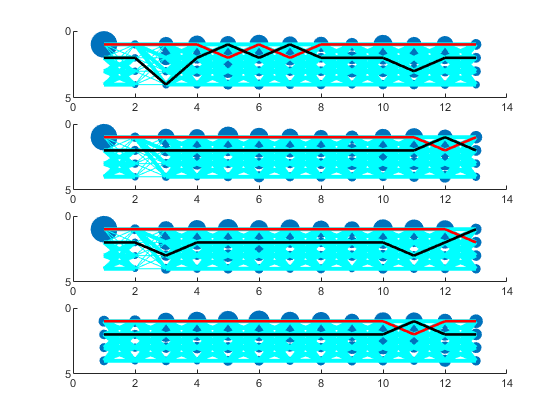

% https://kr.mathworks.com/help/matlab/ref/scatter.html
figure;

emission_plot = zeros(npair, 3, nbest * nframe);
for p = 1:npair
    for ibest = 1:nbest
        for iframe = 1:nframe
            emission_plot(p,1,(ibest-1) * nframe + iframe) = iframe;
            emission_plot(p,2,(ibest-1) * nframe + iframe) = ibest;
            emission_plot(p,3,(ibest-1) * nframe + iframe) = 1 + 400 * 10^(emission1_bak(p, iframe, ibest));
        end
    end
end

hold on;
for p=1:npair
    subplot(npair,1,p);
    scatter(...
        squeeze(emission_plot(p, 1,:)), ... % x range (x data for scatter)
        squeeze(emission_plot(p, 2,:)), ... % y range (y data for scatter)
        squeeze(emission_plot(p, 3,:)), ... % radius
        'filled');     
    axis ij;
    ylim([0 nbest+1]); % for readability
end

hold on;
max_linewidth = 1+max(max(max(max(transition1))));
for p=1:npair
    subplot(npair, 1, p);
    for t = 2:nframe
        for n = 1:nbest
            for nprev = 1:nbest
                line([t-1 t], ... % x data
                    [nprev n], ... % y data
                    'LineWidth', 10^(transition1(p,t,n,nprev))*3,... % tuning
                    'Color','cyan');
            end
        end
    end
end

hold on;
for p = 1:npair
    subplot(npair,1,p);
    for t = 2:nframe
        line([t-1 t], [bestpath1(p,t-1,1) bestpath1(p,t,1)], ...
            'LineWidth', 2, ...
            'Color', 'red');
        line([t-1 t], [bestpath1(p,t-1,2) bestpath1(p,t,2)], ...
            'LineWidth', 2, ...
            'Color', 'black');
    end
end

## multi channel viterbi - state define

nbest2 = 2;
nstate = nbest2 ^ npair;
g = zeros(nstate, npair);
tmp_row = zeros(3,1);
l = 1;
for ibest = 1:nbest2
    [g, l] = fill_all_comb(1, npair, ibest, nbest2, tmp_row, g, l);
end

disp(g);

     1     1     1     1
     1     1     1     2
     1     1     2     1
     1     1     2     2
     1     2     1     1
     1     2     1     2
     1     2     2     1
     1     2     2     2
     2     1     1     1
     2     1     1     2
     2     1     2     1
     2     1     2     2
     2     2     1     1
     2     2     1     2
     2     2     2     1
     2     2     2     2



## multi channel viterbi - emission, trans prob

emission2 = zeros(nframe, nstate);

diff2 = zeros(nframe, nstate, nstate); % do not using 1st idx
transition2 = zeros(nframe, nstate, nstate); % do not using 1st idx

for t = 1:nframe
    for l = 1:nstate
        for m = 1:npair
            ibest = bestpath1(m, t, g(l,m));
            if gcc_nbest(m,t,ibest) > 0
                emission2(t, l) = emission2(t, l) + log10(gcc_nbest(m,t,ibest));
            else
                emission2(t, l) = emission2(t, l) + -1000;
            end
            
        end
    end
end

for t = 2:nframe
    for l = 1:nstate
        for lprev = 1:nstate
            for m = 1:npair
                ibest = bestpath1(m, t, g(l,m));
                jbest = bestpath1(m, t, g(lprev,m));
                transition2(t,l,lprev)...
                    = transition2(t,l,lprev)...
                    + transition1(m,t,ibest,jbest);
            end
        end
    end
end

## multi channel viterbi - searching

score2 = zeros(nframe, nstate, nstate);
score2_table = zeros(nframe, nstate);
back2_table = zeros(nframe, nstate);

for l = 1:nstate
    score2_table(1,l) = emission2(1,l);
end

for t = 2:nframe
    for l = 1:nstate
        for lprev = 1:nstate
             score2(t,l,lprev) = ...
                score2_table(t-1,lprev) + ...
                25*transition2(t,l,lprev) + ... 
                1*emission2(t,l);
            
        end
        [score2_table(t,l), back2_table(t,l)] = max(score2(t,l,:));
    end
end

bestpath2 = zeros(nframe,1); % state idx stored.

[dummy, bestpath2(end)] = max(score2_table(end,:));

for back_t = 0:(nframe-2)        
    t = nframe - back_t;
    bestpath2(t-1) = back2_table(t,bestpath2(t));
end


besttdoa = zeros(npair, nframe);
bestgcc2 = zeros(npair, nframe);

for t = 1:nframe
    for p = 1:npair
        l = bestpath2(t);
        ibest = bestpath1(p, t, g(l,p));
        besttdoa(p,t) = tdoa_nbest(p,t,ibest);
        bestgcc2(p,t) = gcc_nbest(p,t,ibest);
    end
end

disp(back2_table(:,:)'); % compare first mic pair trellis plot

     0     1     1     1     1     9     1     9     1     1     2     2     5
     0     1     1     1     1     9     1     9     1     1     1     1     5
     0     1     1     1     1     9     1     9     1     1     2     2     5
     0     1     1     1     1     9     1     9     1     1     1     1     5
     0     1     1     1     1     9     1     9     1     1     2     2     5
     0     1     1     1     1     9     1     9     1     1     1     1     5
     0     1     1     1     1     9     1     9     1     1     2     2     5
     0     1     1     1     1     9     1     9     1     1     1     1     5
     0     1     1     1     1     9     1     1     1     9     2     2     5
     0     1     1     1     1     9     1     1     1     9     1     1     5
     0     1     1     1     1     9     1     1     1     9     2     2     5
     0     1     1     1     1     9     1     1     1     9     1     1     5
     0     1     1     1     1     9     1     1    

disp(bestpath2');

     1     1     1     1     9     1     9     1     1     1     2     5     3



disp(besttdoa);

     0     0     3     3     2     3     4     3     4     4     4     3     4
     0     0     3     2     2     2     3     2     2     2     3     0     3
     0     0     0     0     0     0     1     1     1     1     1     1    -2
     2     0    -1    -1    -1    -1    -1    -1     0    -1     0    -1    -1



disp(bestgcc2);

  1 ~ 11번 열

    1.0000    0.0958    0.3159    0.4406    0.3951    0.5243    0.3628    0.3320    0.2340    0.5149    0.3196
    1.0000    0.1247    0.4047    0.3721    0.6302    0.4966    0.4161    0.2995    0.2472    0.3946    0.4590
    1.0000    0.1352    0.3670    0.4736    0.5887    0.4686    0.5411    0.4187    0.3534    0.5520    0.5322
    0.1688    0.1912    0.4108    0.5103    0.5960    0.6375    0.5026    0.4790    0.3169    0.4470    0.4333

  12 ~ 13번 열

    0.3942    0.1622
    0.3271    0.2190
    0.4496    0.1741
    0.3144    0.2648



## multi channel viterbi - plot

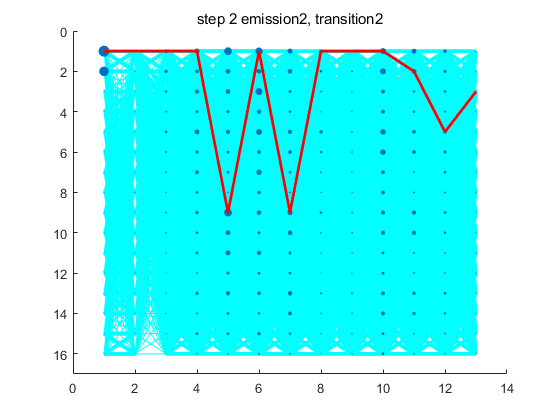

% https://kr.mathworks.com/help/matlab/ref/scatter.html
figure;

%figure;
%max_linewidth = 1+max(max(max(max(transition2))));

title(sprintf('step 2 emission2, transition2'));
for t = 2:nframe
    for l = 1:nstate
        for lprev = 1:nstate
            line([t-1 t], ... % x data
                [lprev l], ... % y data
                'LineWidth', 3*(exp(transition2(t,l,lprev))),... % tuning
                'Color','cyan');
            axis ij;
        end
    end
end
% ylim([0 nstate+1]);
% xlim([0 nframe+1]);

emission2_plot = zeros(3, nstate * nframe);

for l = 1:nstate
    for iframe = 1:nframe
        
       
        emission2_plot(1,(l-1) * nframe + iframe) = iframe;
        emission2_plot(2,(l-1) * nframe + iframe) = l;
        emission2_plot(3,(l-1) * nframe + iframe) = 1 + 400 * 10^(emission2(iframe, l));
    end
end

hold on;
scatter(...
    squeeze(emission2_plot(1,:)), ... % x range (x data for scatter)
    squeeze(emission2_plot(2,:)), ... % y range (y data for scatter)
    squeeze(emission2_plot(3,:)), ... % radius
    'filled');

hold on;
for t = 2:nframe
    line([t-1 t], [bestpath2(t-1) bestpath2(t)], ...
        'LineWidth', 2, ...
        'Color', 'red');
end


axis ij;
ylim([0 nstate+1]); % for readability
xlim([0 nframe+1]);

## compute local xcorr

tmp_localxcorr = zeros(nmic, nmic, nframe);
localxcorr = zeros(nmic, nframe);

mic2refpair = zeros(nmic,1);
mic2refpair(ref_mic) = 0;

for p = 1:npair
    m = micpair(ref_mic,p);
    mic2refpair(m) = p;
end

for t = 1:nframe
    ref_st = (t-1) * 4000 + 1;
    ref_ed = min(ref_st + 8000 - 1, nsample);
    
    for m1 = 1:(nmic-1)
        for m2 = (m1+1):nmic
            
            if m1 == ref_mic
                st1 = ref_st;
                ed1 = ref_ed;
            else
                p = mic2refpair(m1);
                st1 = max(1,ref_st + besttdoa(p,t));
                ed1 = min(nsample, ref_ed + besttdoa(p,t));
            end
            
            if m2 == ref_mic
                st2 = ref_st;
                ed2 = ref_ed;
            else
                p = mic2refpair(m2);
                st2 = max(1,ref_st + besttdoa(p,t));
                ed2 = min(nsample, ref_ed + besttdoa(p,t));
            end
            
            buf1 = x(m1,st1:ed1);
            buf2 = x(m2,st2:ed2);
            
            ener1 = sum(buf1(:).^2);
            ener2 = sum(buf2(:).^2);
            
            min_ed = min(ed1-st1, ed2-st2) + 1;
            tmp_localxcorr(m1,m2,t)...
                = sum(...
                buf1(1:min_ed) .* buf2(1:min_ed)...
                / (ener1 * ener2));
        
            tmp_localxcorr(m2,m1,t) = tmp_localxcorr(m1,m2,t);
        end
    end
end

localxcorr = squeeze(sum(tmp_localxcorr,1));
disp(localxcorr);

  1 ~ 11번 열

    0.1241    0.0749    0.0660    0.0619    0.0644    0.0685    0.0618    0.0604    0.0704    0.0804    0.1006
    0.1103    0.0666    0.0572    0.0551    0.0586    0.0606    0.0546    0.0525    0.0610    0.0715    0.0893
    0.1528    0.0899    0.0769    0.0698    0.0722    0.0762    0.0712    0.0696    0.0833    0.1025    0.1277
    0.1483    0.0849    0.0678    0.0613    0.0635    0.0679    0.0632    0.0634    0.0765    0.0926    0.1167
    0.1046    0.0605    0.0485    0.0453    0.0488    0.0526    0.0481    0.0479    0.0570    0.0663    0.0842

  12 ~ 13번 열

    0.1483    0.1360
    0.1323    0.1254
    0.1863    0.1722
    0.1719    0.1614
    0.1273    0.1183



## compute sum weight

out_weight = ones(nmic, nframe) * ( 1 / nmic);
alpha = 0.05;


for t = 1:nframe
    
    if sum(localxcorr(:,t)) == 0
        localxcorr(:,t) = 1 / nmic;
    end
    
    localxcorr(:,t) = localxcorr(:,t) / sum(localxcorr(:,t));
    
    for m = 1:nmic
        if m == ref_mic
             out_weight(m,t) = ...
            (1-alpha) * out_weight(m,max(1,t-1)) ...
            + alpha * localxcorr(m,t);    
        
        else
            p = mic2refpair(m);
            if noise_filter(p,t) == 0
                out_weight(m,t) = ...
                    (1-alpha) * out_weight(m,max(1,t-1)) ...
                    + alpha * localxcorr(m,t);    
            end
        end
    end
    
    out_weight(:,t) = out_weight(:,t) / sum(out_weight(:,t));
    
end

disp(mic2refpair);

     1
     2
     3
     4
     0



disp(out_weight);

  1 ~ 11번 열

    0.2000    0.2002    0.2006    0.2011    0.2015    0.2020    0.2022    0.2024    0.2024    0.2020    0.2016
    0.2000    0.2002    0.1992    0.1986    0.1982    0.1976    0.1969    0.1960    0.1949    0.1938    0.1927
    0.2000    0.2002    0.2023    0.2041    0.2056    0.2070    0.2086    0.2100    0.2115    0.2133    0.2150
    0.2016    0.2030    0.2036    0.2038    0.2039    0.2042    0.2045    0.2051    0.2058    0.2067    0.2077
    0.1982    0.1965    0.1943    0.1923    0.1907    0.1892    0.1878    0.1866    0.1854    0.1842    0.1831

  12 ~ 13번 열

    0.2012    0.2007
    0.1917    0.1909
    0.2164    0.2176
    0.2085    0.2094
    0.1822    0.1814



## Channel sum

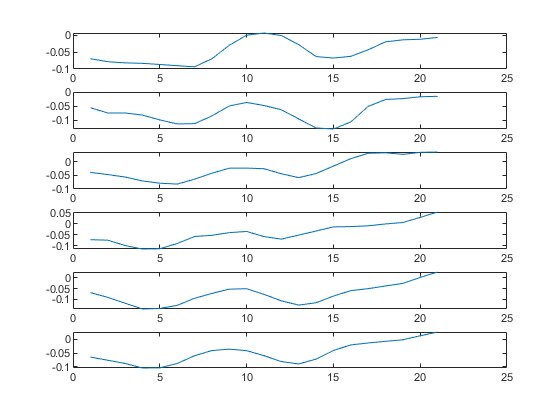

out_x = zeros(1,nsample);

figure;
for t = 1:nframe
    ref_st = (t-1) * 4000 + 1;
    ref_ed = min(ref_st + 8000 - 1, nsample);
    
    for m = 1:nmic   
        if m == ref_mic
            st = ref_st;
            ed = ref_ed;
        else
            p = mic2refpair(m);
            st = max(1,ref_st + besttdoa(p,t));
            ed = min(nsample, ref_ed + besttdoa(p,t));
        end
       
        triwin = triang(8000)';
        if t == 1
            triwin(1:4000) = 1;
        end
%         size(out_x(ref_st:min_ed))
%         size(triwin(1:min(8000,min_ed-ref_st+1)))
        diff = 0;
        if (ref_ed - ref_st) ~= (ed - st) % if buf is small (always)
          
                diff = ref_ed - ed;
          
        end
        out_x(ref_st:ref_ed-diff)...
            = out_x(ref_st:ref_ed-diff)...   
            + (squeeze(x(m,st:ed))...
            * out_weight(m,t)...
            .* triwin(1:min(8000,ed-st+1)));
            %* overall_weight...
            
        
            %.* triwin(min(8000,min_ed-ref_st+1))...
            %* out_weight(m,t));
%         plot(out_x);
    end
end

ref_st = (t) * 4000 + 1;
ref_ed = min(ref_st + 8000 - 1, nsample);

for m = 1:nmic
    if m == ref_mic
        st = ref_st;
        ed = ref_ed;
    else
        p = mic2refpair(m);
        st = max(1,ref_st + besttdoa(p,t));
        ed = min(nsample, ref_ed + besttdoa(p,t));
    end
    buf = squeeze(x(m,st:ed));
    diff = (ref_ed - ref_st) - (ed-st);
    if diff > 0
        buf = [buf, zeros(1,diff)];
    else
        buf = buf(1:end-diff);
    end
    
    triwin = triang(8000)';
    triwin(4001:end) = 1;
    %buf = buf .* triwin(1:size(buf,2));
    out_x(ref_st:ref_ed)...
            = out_x(ref_st:ref_ed)...   
            + (buf...
            * out_weight(m,t)...
            .* triwin(1:min(8000,ref_ed-ref_st+1))...
            * overall_weight);
        
    if ref_ed < nsample
        out_x(ref_ed+1:end) = out_x(ref_ed+1:end) + (x(ref_mic,ref_ed+1:end) * out_weight(m,t) * overall_weight);
    end
end

figure;
subplot(6,1,1); plot(x(1,16000:16020)); % (+) delayed
subplot(6,1,2); plot(x(2,16000:16020)); % ref_mic assumed
subplot(6,1,3); plot(x(3,16000:16020)); % no idea
subplot(6,1,4); plot(x(4,16000:16020)); % no idea
subplot(6,1,5); plot(x(5,16000:16020)); % no idea
subplot(6,1,6); plot(out_x(16000:16020)); % no idea

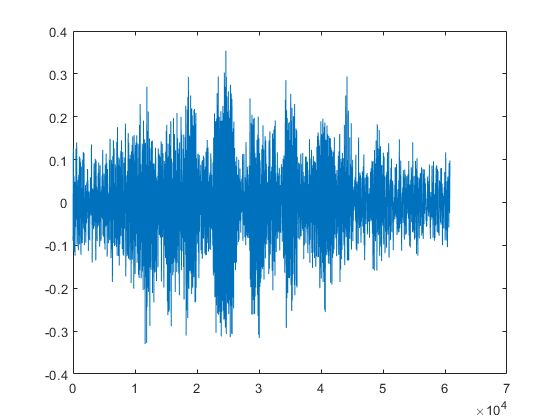


figure;
subplot(6,1,1); plot(x(1,16000:16020)); % (+) delayed
subplot(6,1,2); plot(x(2,16000:16020)); % ref_mic assumed
subplot(6,1,3); plot(x(3,16000:16020)); % no idea
subplot(6,1,4); plot(x(4,16000:16020)); % no idea
subplot(6,1,5); plot(x(5,16000:16020)); % no idea
subplot(6,1,6); plot(out_x(16000:16020)); % no idea


figure; plot(out_x);

audiowrite('enhance_1008.wav',out_x,16000);

function [table, l] = fill_all_comb(ipair, npair, ibest, nbest, tmp_row, table, l)
    tmp_row(ipair) = ibest;
    %fprintf('ipair: %d ibest: %d l: %d\n', ipair, ibest, l);
    
    if ipair == npair    
        for j = 1:npair
            table(l, j) = tmp_row(j);
        end
        l = l + 1;
    else
        for ibest = 1:nbest
            [table, l] = fill_all_comb(ipair + 1, npair, ibest, nbest, tmp_row, table, l);
        end
    end
end